# "What's New for Managing, Testing, and Building your MATLAB Code" Workshop Guide

This workshop provides a step-by-step guide to using some of the latest features in MATLAB focused on helping you build more robust applications.

In this workshop, you will:

- open a GitHub® repository in MATLAB Online with a single click

- explore the repository history using the Branch Manager

- understand file relationships and identify a dependency issue using the Dependency Analyzer

- identify issues in the code using the `codeIssues` function

- configure the Code Analyzer to enable more strict code issue detection

- programmatically package a toolbox using the `ToolboxOptions` object

- automate the testing and packaging of a toolbox using the build tool

## Part 1:  Requirements for the workshop

The following steps cover all of the things you will need to successfully complete the workshop:

**1A)  MathWorks account**

- Create a free MathWorks account at:  [**https://www.mathworks.com/mwaccount/register**](https://www.mathworks.com/mwaccount/register)

**1B)  Google Chrome web browser**

- Google Chrome is the recommended web browser when using MATLAB Online

- Go to:  [**https://www.google.com/chrome/downloads**](https://www.google.com/chrome/downloads)

## Part 2:  Open the workshop repository in MATLAB Online

To help you get started with this workshop, we are hosting the workshop directly on GitHub, and providing an easy "Open in MATLAB Online" badge to automatically clone the repository to your free MATLAB Online account, and even open this `WorkshopGuide.mlx` file for you automatically!

Let's get started!

**2A)  Go to:  **[**https://github.com/mathworks/Expo-2023-Whats-New-for-Managing-Testing-and-Building-your-MATLAB-Code**](https://github.com/mathworks/Expo-2023-Whats-New-for-Managing-Testing-and-Building-your-MATLAB-Code)

**2B)  Press the "Open in MATLAB Online" badge (under the file list, near the badges)**

Below the repository's file list, you will find an "Open in MATLAB Online" badge.

              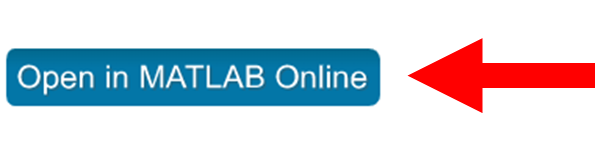

Clicking the "Open in MATLAB Online" badge will start the process of:

- logging you into MATLAB Online

- asking for permission to copy files to your MATLAB account and run code

- cloning the repository to your MATLAB account

- opening the workshop project

- opening the `WorkshopGuide.mlx` file

**2C)  Log into your MathWorks account (only if you are not already logged in)**

If you are not already logged into your MathWorks account, you will be asked to log in before you can continue.

              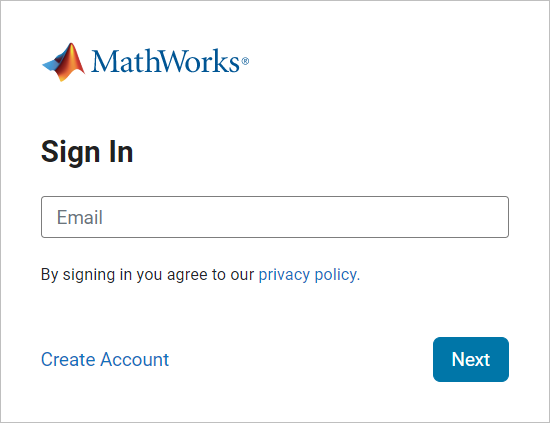

If you do not have a MathWorks account, you will need to create one before continuing.

**2D)  Give MATLAB Online permission to save and open the files in your MATLAB Online account**

As part of our commitment to security, MATLAB Online will ask you for permission to save the workshop files to your MATLAB Online account, and allow MATLAB Online to execute some MATLAB code automatically (for example, to automatically open the project and the `WorkshopGuide.mlx` file for you).

In the following dialog, please check the "I understand..." box, and press the "Save and Open" button.

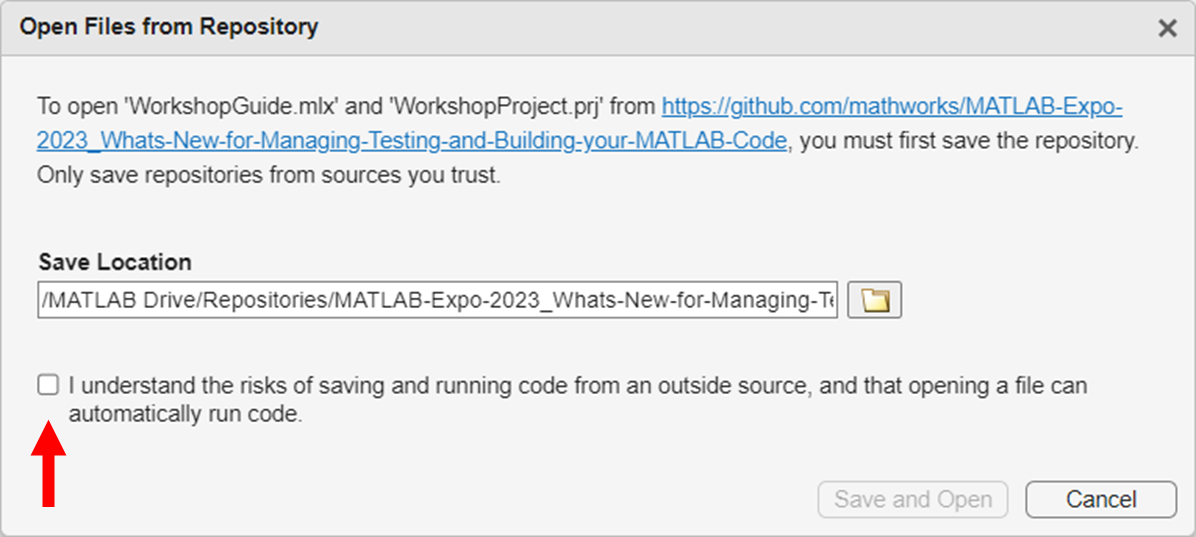

With that, you're ready to start the "What's New for Managing, Testing, and Building your MATLAB Code" workshop!

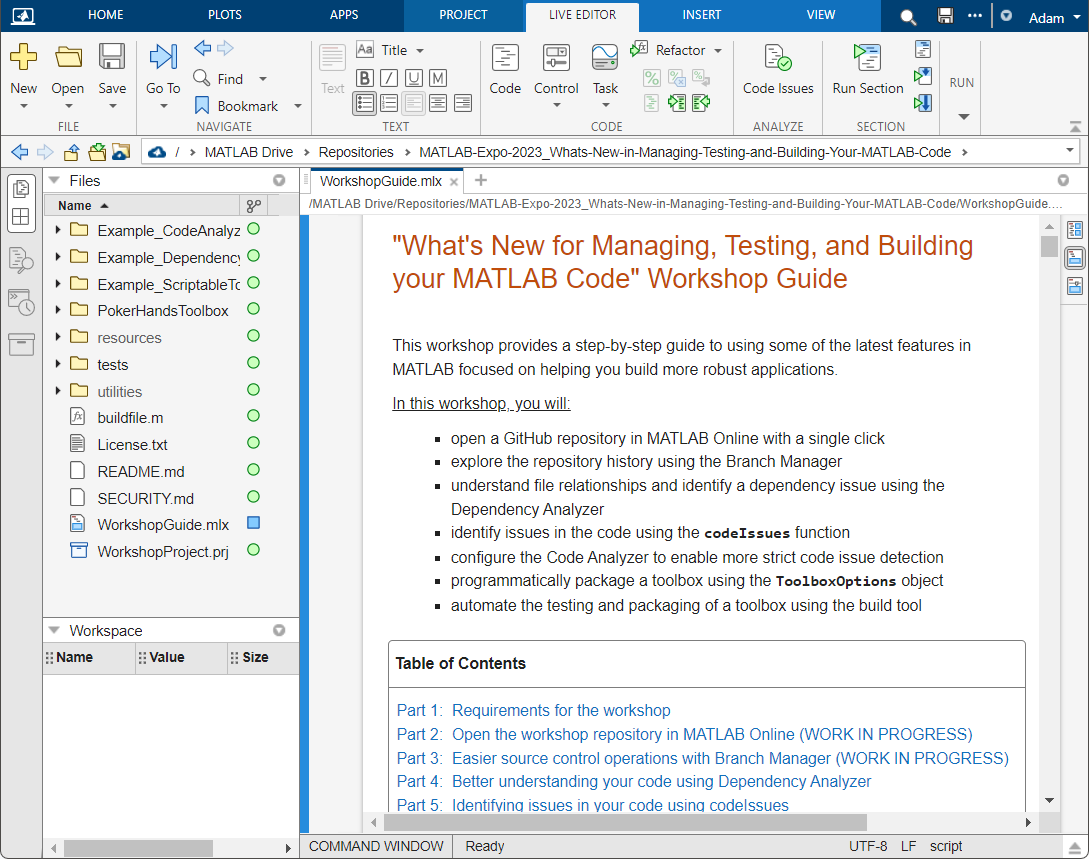

## Part 3:  Easier source control operations with Branch Manager

When getting started with a new project, I find it useful to take a quick peek at the commit history of a repository to see:

- How much active work is going on in this repository?

- Are there multiple contributors to the repository?

- Do they use multiple branches to manage concurrent development?

- If I were to create a new branch for my work, is there a pattern to the names they use for their branches that I should follow?

- etc.

This helps me feel like I'm getting a head start in better understanding the team I'm going to work with, and help me fit in with their existing development workflow.

The Branch Manager is a great way to explore the repository history!

**3A)  Launch the Branch Manager**

To launch the Branch Manager, click on the "Branch Manager" icon in the project toolstrip.

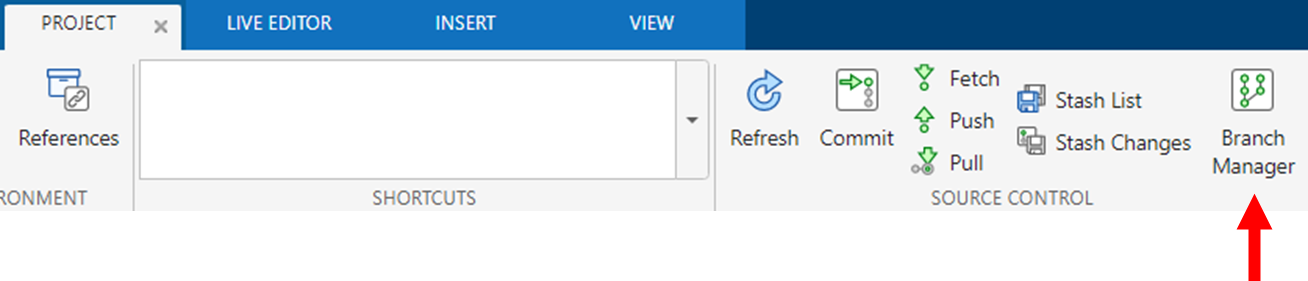

**3B)  Explore the repository history**

The Branch Manager lets you:

- see the entire commit history and all files changed with each commit

- commit, merge, push, pull, and fetch changes

- create, switch, and delete branches and tags

- search commit messages

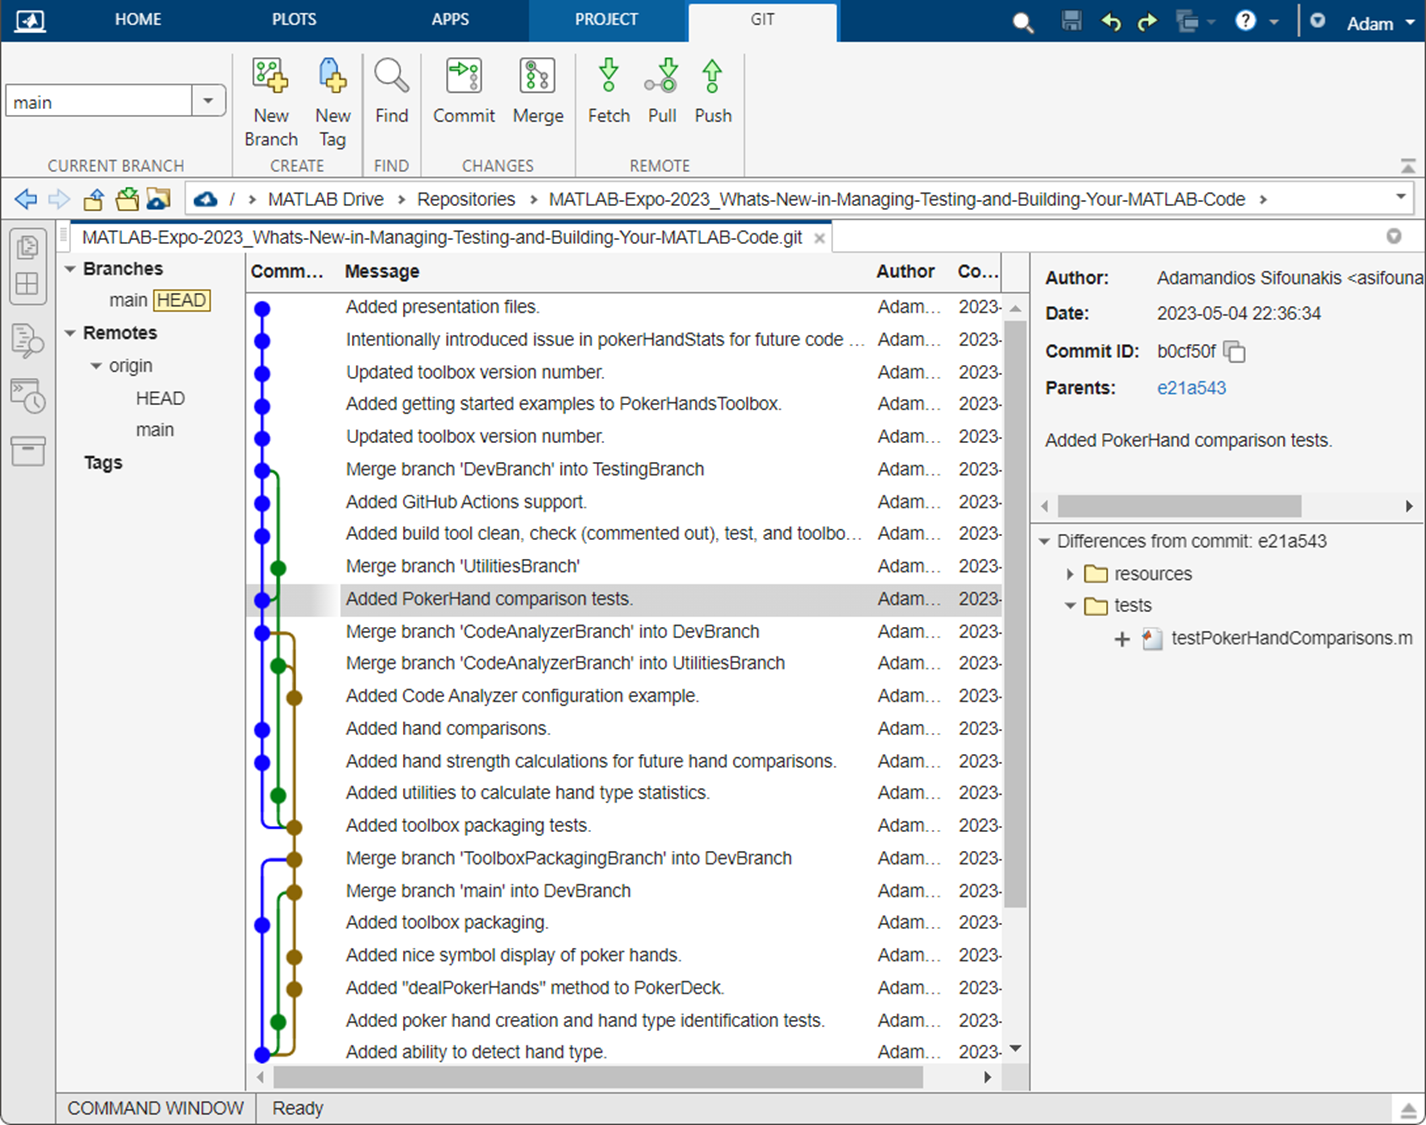

***Note:***  Double-clicking on the tab in the Branch Manager will expand the Branch Manager to fill your available window space. This can be helpful if the initial panel size is too small.

              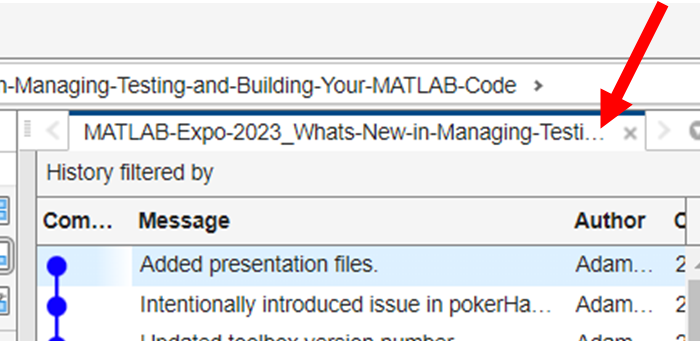

**3C)  Create a new branch for our workshop**

Let's create a new branch for the work we'll be doing during our workshop.

You can create a new branch using the "New Branch" button in the toolstrip, and you can name the new branch whatever you'd like.

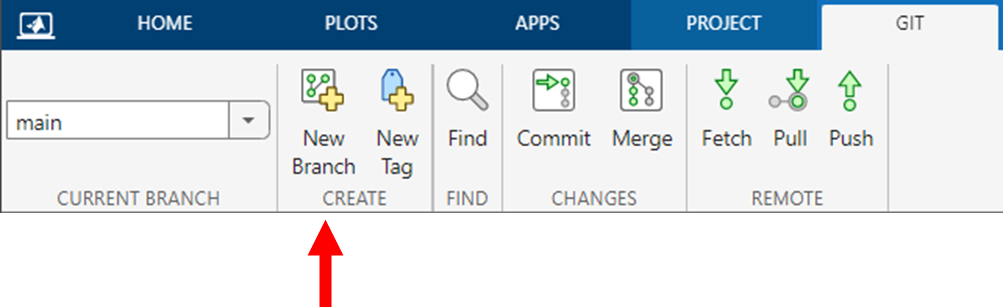

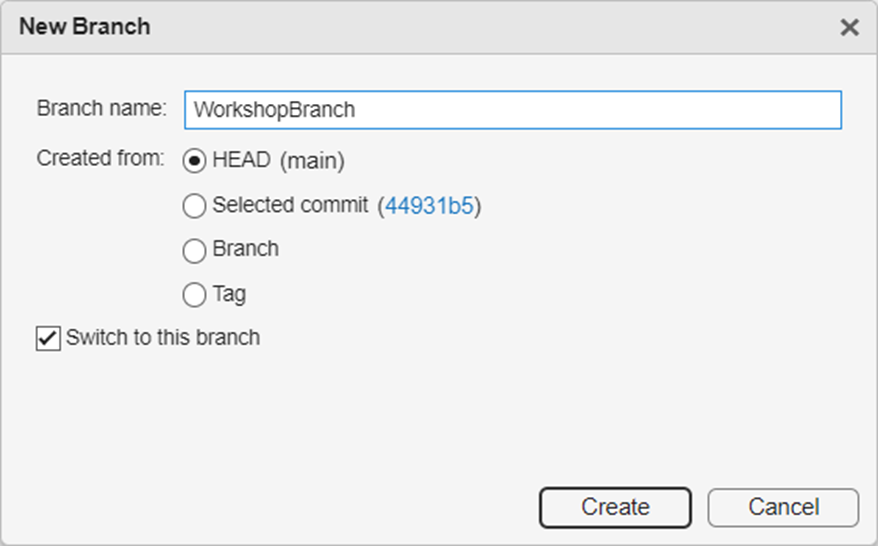

Once you've created your new branch, you can close the Branch Manager using the "X" on the Branch Manager tab.

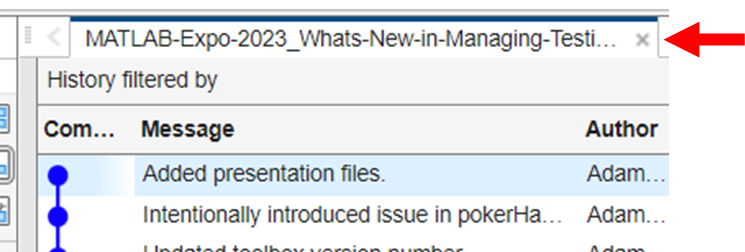

You're now ready to start making changes to the code in your own private branch!

## Part 4:  Better understanding your code using Dependency Analyzer

Another great way to better understand a codebase you are getting started with, is using the Dependency Analyzer to visualize how all the files in the repository relate to each other. That can show you:

- How many files are in the repository?

- How complex are the file relationships in the repository?

- Are there smaller, less complicated parts of the repository that might be easier to understand or get started with?

- Are there any missing files or issues that might cause problems in this repository?

Let's take a look at the Dependency Analyzer!

**4A)  Launch the Dependency Analyzer**

To launch the Dependency Analyzer, click on the "Dependency Analyzer" icon in the "Tools" section of the projects toolstrip.

              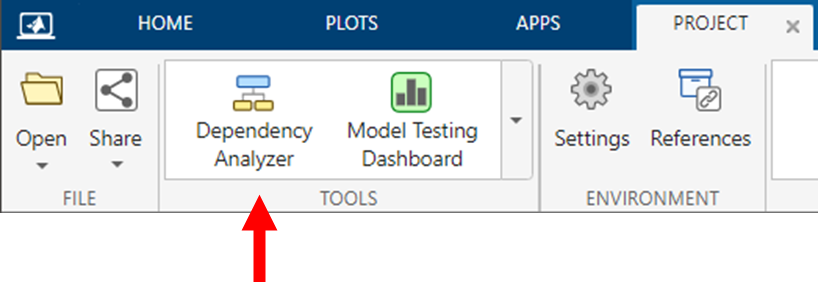

**4B)  Explore the dependency graph**

The dependency graph is an interactive view of all of the file dependencies in the project.

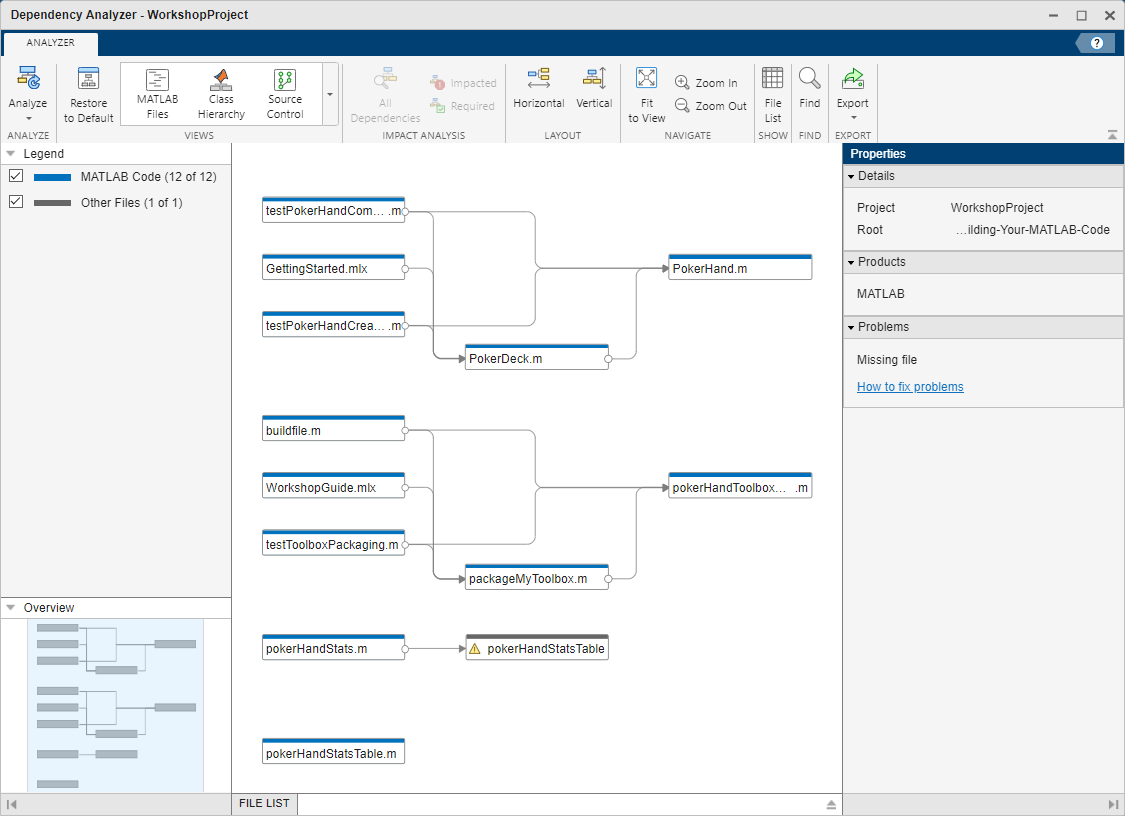

You can click and drag any of the boxes however you'd like, or even change the layout using the buttons in the Dependency Analyzer toolstrip.

***Note:***  You can minimize MATLAB Apps (like Dependency Analyzer) at any time, and re-open them via the window switching icons on the bottom right area of the MATLAB interface.

              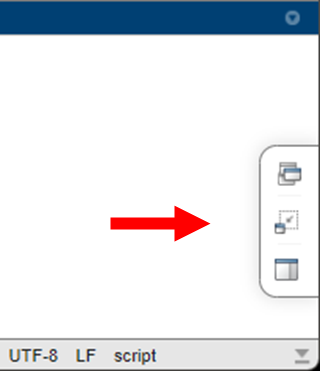

**4C)  Identifying problems using Dependency Analyzer**

Dependency problems will be indicated with a warning symbol (⚠️) within the dependency graph, and indicated with text in the "Problems" section of the right-hand side "Properties" panel.

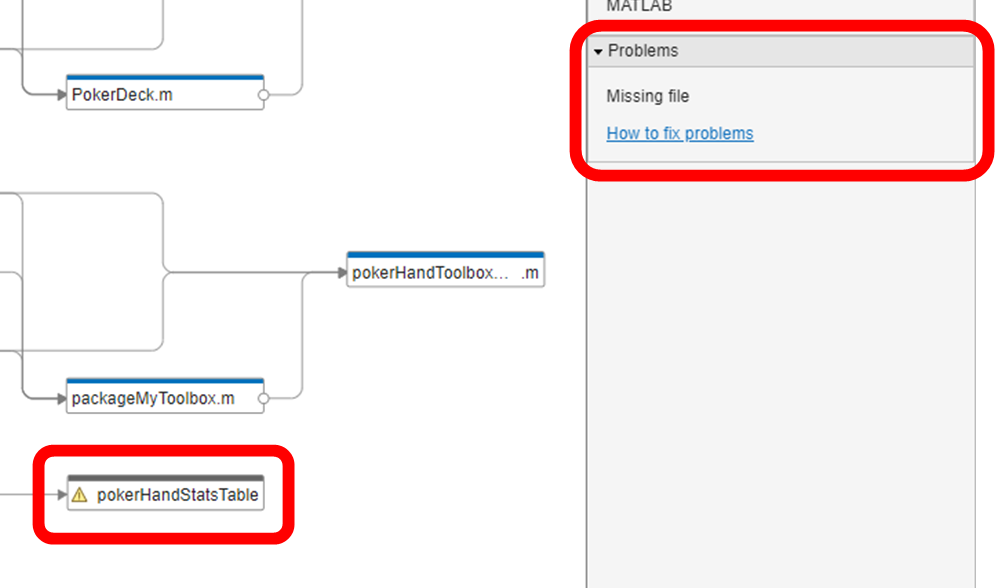

Hovering over the "Missing file" portion of the "Problems" panel will reveal a magnifying glass, which can be used to highlight all files in the dependency graph with that specific issue.

              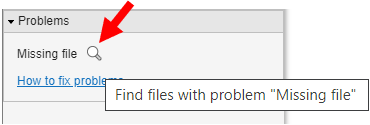

              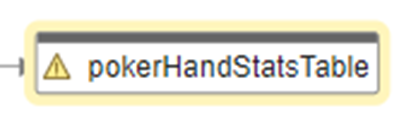

It appears that we are missing the "`pokerHandStatsTable`" file.

**4D)  Resolve the dependency issue**

There are several reasons for a missing file:

- A typo in a variable or function name

- The file is missing from the project

- The file is part of the project, but it's parent folder is not on the path

Looking at the dependency graph, we can see that there is another "`pokerHandStatsTable.m`" file within the project, but it is not connected to anything. This sometimes indicates that the file is part of the project, but it is not on the project path, so no other file can see it.

Selecting the single "`pokerHandStatsTable.m`" file allows us to see that this file is located in the "`utilities`" folder of our project, and it appears this folder is not on the project path.

              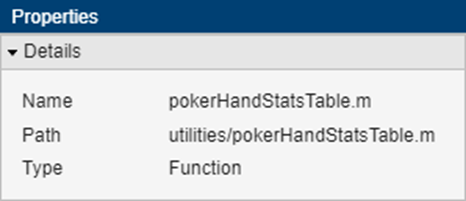

Looking at the project file list, we can tell that the "`utilities`" folder is not on the project path because it is missing the folder icon in the "Status" column.

              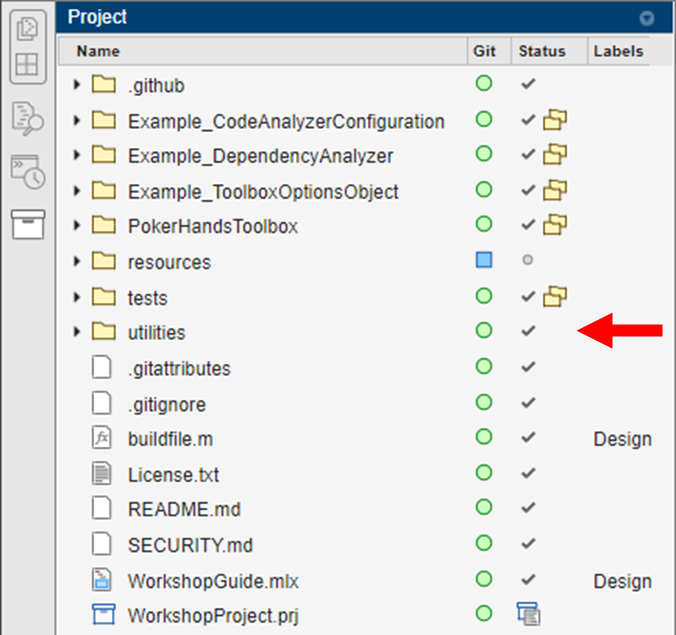

We can add the "`utilities`" folder to the project path by right-clicking on the folder and selecting "Add to Project Path > Selected Folder."

              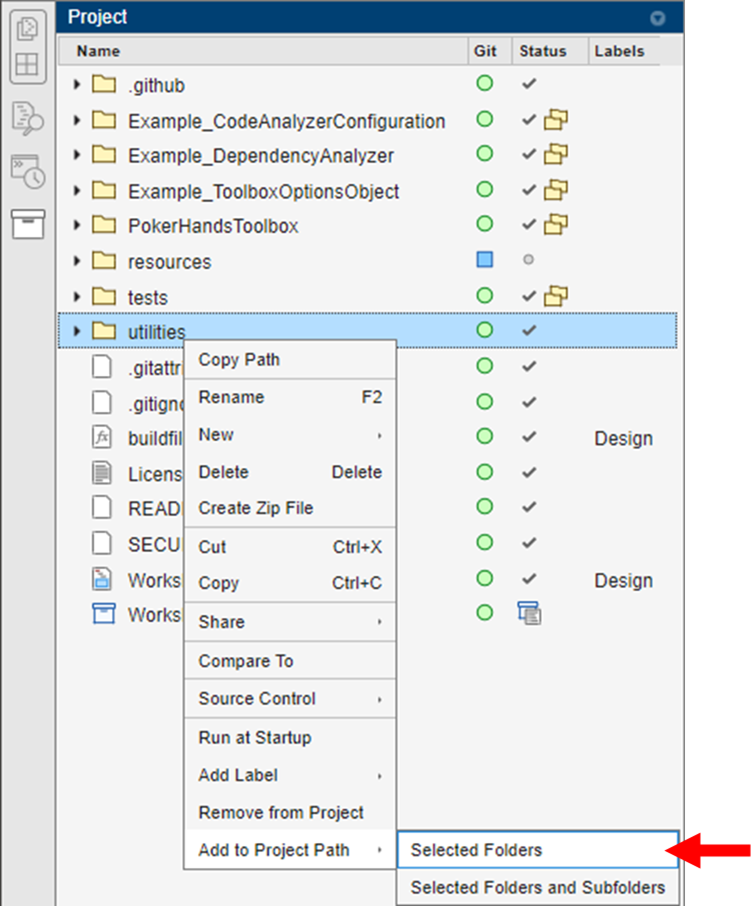

We can now re-run the dependency analysis using the "Analyze" button in the top left corner of Dependency Analyzer.

              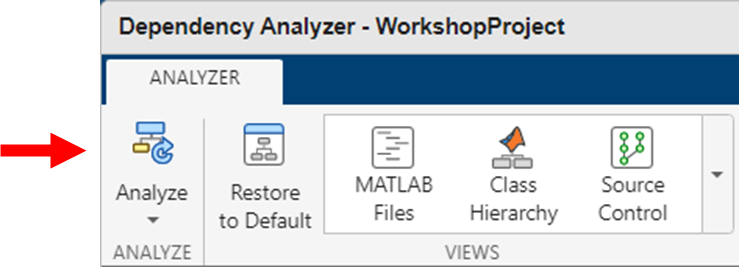

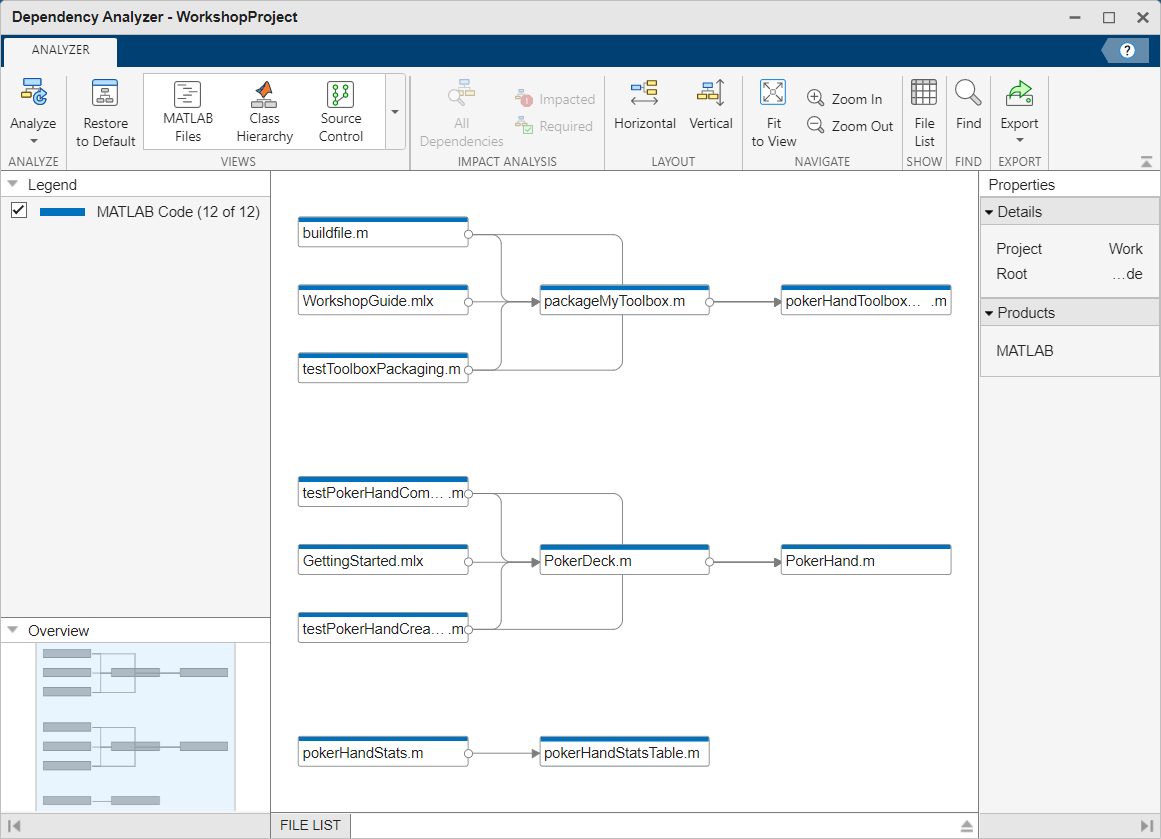

The `pokerHandStatsTable.m` item is no longer marked as missing, and our dependency graph no longer shows any problems.

Congratulations! You just used Dependency Analyzer to better understand your code file relationships and resolve a problem within your project!

## Part 5:  Identifying issues in your code using codeIssues

The MATLAB Editor is very helpful in identifying coding issues as you type, but it can be tedious to open every single file in your project to see their issues.

In MATLAB R2022b, we introduce a new Code Analyzer app that lets you analyze an entire folder of files (and any files in subfolders), and display the issues in an interactive report.

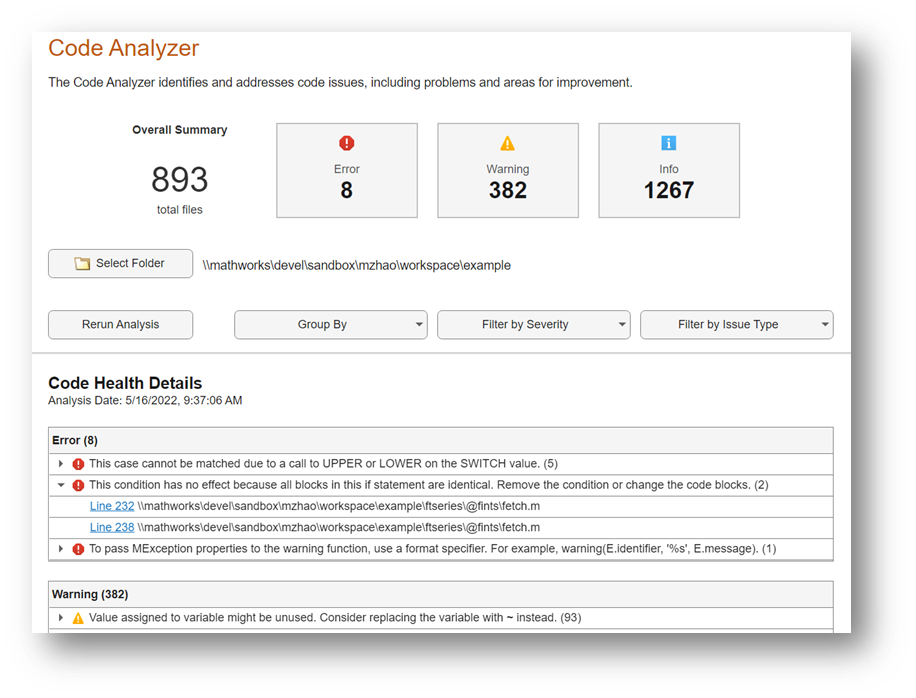

We also introduced the `codeIssues` function to allow you to programmatically accomplish the same task, and enable automated and continuous integration workflows.

Let's use the `codeIssues` function to see all of the issues in our project!

**5A)  Use the **`codeIssues`** function to see all of the issues in your project**

Run the following code at the Command Window:

codeIssues

The `codeIssues` object contains a lot of useful information, and we can quickly see that our entire codebase only has 1 warning. That's pretty good!

Clicking on a hyperlinked file name will conveniently take us directly to that specific issue in the file.

Let's leave this issue alone for now, and we'll revisit it in later steps of the workshop.

## Part 6:  Customizing the issues Code Analyzer can find using a Code Analyzer configuration

MATLAB ships with a default Code Analyzer configuration that recommends lots of good programming practices. However, you may want to promote even better coding practices by increasing the number of issues the Code Analyzer can find, or raising the severity of existing Code Analyzer checks.

In MATLAB R2023a, we introduced the ability to provide a customized the Code Analyzer configuration that will apply to a folder code (and all of its subfolders). This Code Analyzer configuration file lives with the code it applies to, can be checked into source control, and will be automatically applied, no matter where your folder of code is moved to.

**6A)  Explore the **[`codeAnalyzerConfiguration.json`](matlab:open('./Example_CodeAnalyzerConfiguration/codeAnalyzerConfiguration.json'))** file**

Let's take a look at the example Code Analyzer configuration file included in this project.

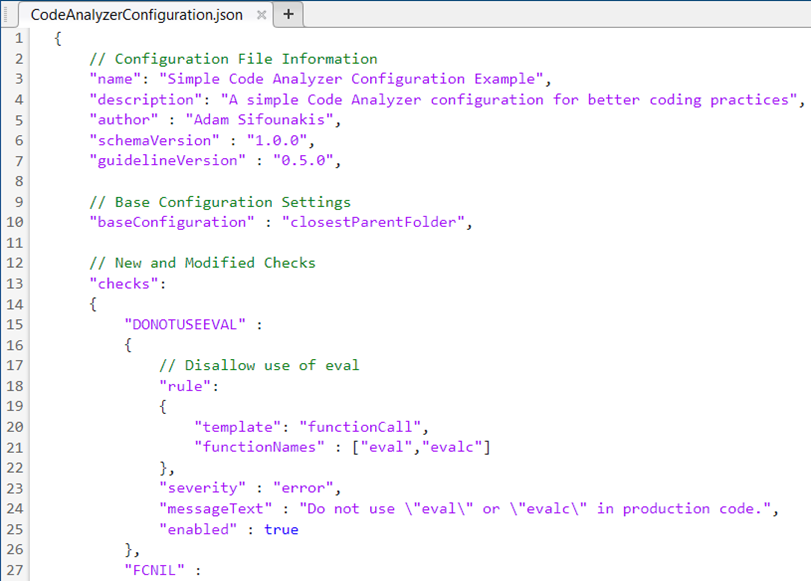

This configuration includes a few changes to MATLAB's default Code Analyzer configuration.

The biggest changes are enabling some of the new configurable checks available in R2023a:

- Disallow "`eval`" and "`evalc`" function usage

- Warn for functions with 10 or more input arguments

- Warn for functions with 10 or more output arguments

- Raise the severity of some existing Code Analyzer checks from "warning" to "error"

**6B)  Apply the Code Analyzer configuration**

To apply the Code Analyzer configuration to the entire project, we need to copy the [`codeAnalyzerConfiguration.json`](matlab:open('./Example_CodeAnalyzerConfiguration/codeAnalyzerConfiguration.json')) file to the "`resources`" folder at the root of the project.

copyfile(fullfile("Example_CodeAnalyzerConfiguration","codeAnalyzerConfiguration.json"),"resources");

Re-running our code analysis now shows us new issues that our more strict Code Analyzer configuration allows us to detect.

codeIssues

We can see that our previous code warning is now an error. By raising its severity from "warning" to "error," we are indicating that this issue can have significant consequences to our code quality, and that we should prioritize fixing it.

Using a custom Code Analyzer configuration is a great way to add more rigorous coding guidance to your projects!

## Part 7:  Scriptable toolbox packaging using the ToolboxOptions object

Being able to programmatically package a toolbox can enable more complete automated workflows, especially in continuous integration systems.

In MATLAB R2023a, we introduced a new [`matlab.addons.toolbox.ToolboxOptions`](https://www.mathworks.com/help/matlab/ref/matlab.addons.toolbox.toolboxoptions.html) object that makes it really easy to programmatically define a toolbox.

**7A)  Explore the toolbox definition**

The [`pokerHandsToolboxDefinition.m`](matlab:open('./Example_ScriptableToolboxPackaging/pokerHandsToolboxDefinition.m')) file shows how we can programmatically define a toolbox.

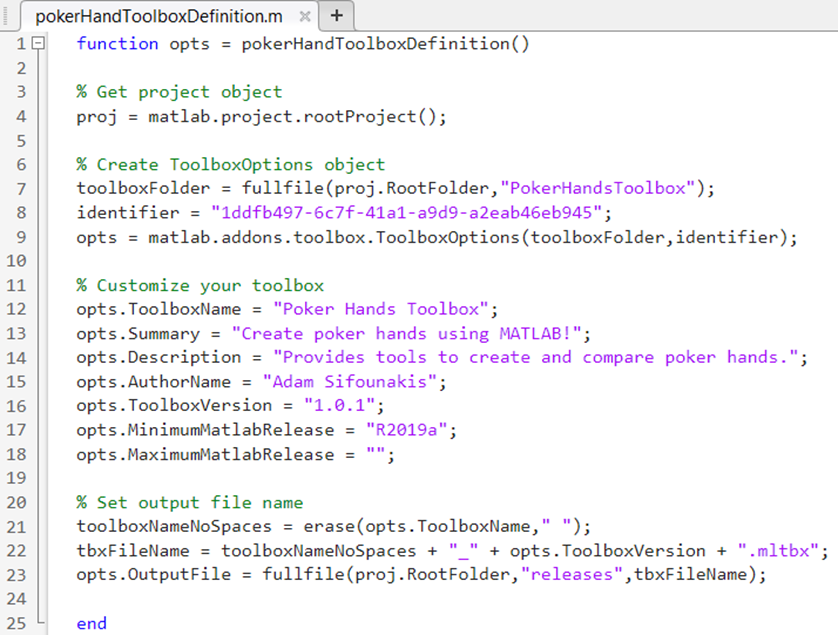

**7B)  Use the ToolboxOptions object to programmatically package a toolbox**

To programmatically package a toolbox, we just need to pass our customized `ToolboxOptions` object to the [`matlab.addons.toolbox.packageToolbox`](https://www.mathworks.com/help/matlab/ref/matlab.addons.toolbox.packagetoolbox.html) function.

The included [`packageMyToolbox.m`](matlab:open('./Example_ScriptableToolboxPackaging/packageMyToolbox.m')) function does exactly this.

              

packageMyToolbox

Congratulations! You just programmatically packaged your first toolbox!

## Part 8:  Automating build operations with the build tool

One of the most challenging aspects of working with an existing codebase is not really knowing where to get started.

- Are there any setup actions that must happen before I can start working with this code?

- What kind of major actions are available for this code? (e.g., testing? code generation? toolbox packaging?)

- Is there a required order to the steps I need to take so that things will work correctly?

- etc.

In MATLAB R2022b, we introduced the [**build tool**](https://www.mathworks.com/help/matlab/matlab_prog/overview-of-matlab-build-tool.html) to help tackle these issues.

The build tool offers a standardized way to define and execute tasks, as well as establish dependencies and order between tasks.

As long as you're using the build tool, anyone will be able to quickly and easily know exactly which tasks are available, and exactly how to run those tasks correctly.

**8A)  Take a look at the available build tool tasks**

To see a list of available build tool tasks, execute the following command at the Command Window:

buildtool -tasks

We can see that there are three available tasks:

- `clean`

- `test`

- `toolbox`

Now that we know which tasks are available, let's run them!

**8B)  Run the clean task**

I love to start with everything all fresh and clean, so let's start with the `clean` task.

You can run the `clean` task using:

buildtool clean

We can see that the `clean` task deleted the MLTBX file we created in **Part 7** of the workshop.

Congratulations! You've just successfully run your very first build tool task!

***Note:***  If you skipped **Part 7** of the workshop, then the buildtool will have reported that it skipped the `clean` task, as there were no files to clean.

**8C)  Run the **`test`** task**

Now, let's run the `test` task.

buildtool test

The `test` task successfully ran all 23 available tests in the project, and found no problems! We're off to a great start!

**8D)  Run the **`toolbox`** task**

Let's package the same toolbox we created in **Part 7** of the workshop, but this time using the `toolbox` task.

buildtool toolbox

There are few interesting things to note about what just happened.

- the `toolbox` task automatically ran the `test` task

- the `test` task was skipped because it was already "up-to-date"

- the `toolbox` task successfully created our toolbox file

What does all of that mean?

- The `toolbox` task seems to depend on the `test` task

- The build tool was smart enough to recognize that nothing had changed since the last time you ran the `test` task, so it skipped the `test` task

- Finally, the build tool successfully ran the `toolbox` task to create our toolbox file

**8E)  Skipping unnecessary tasks**

As we noticed in the last step, the build tool can be smart enough to skip tasks whose inputs and outputs have not changed. This feature is called "incremental build," and it can save lots of time as your build process becomes more complex and time-consuming. The incremental build feature was introduced in MATLAB R2023a, and information on how to enable incremental builds can be found [here](https://www.mathworks.com/help/matlab/matlab_prog/improve-performance-with-incremental-builds.html).

To see incremental build in action, let's try running the `toolbox` task again.

buildtool toolbox

In this case, both the `test` task and the `toolbox` task were skipped, since the inputs or outputs of both tasks had not changed since the last time we ran them.

**8F)  Taking a look at how tasks are defined in **[`buildfile.m`](matlab:open('./buildfile.m'))

It's awesome that we could very easily see which tasks were available for this repository, and we didn't really need to know anything to be able to run the available tasks successfully.

Now, let's take a look inside [`buildfile.m`](matlab:open('./buildfile.m')) at how these tasks were defined.

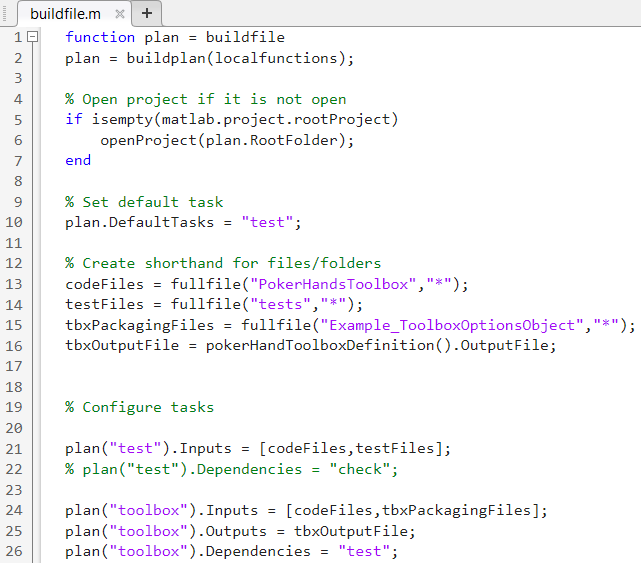

There are a few interesting things to note about the build file:

- The build file creates a `plan` object

- Any local functions inside [`buildfile.m`](matlab:open('./buildfile.m')) that end with "`Task`" are automatically recognized as build tasks (e.g., the "`cleanTask`" local function creates the "**c**`lean`" task)

- You can easily set the `Inputs`, `Outputs`, and `Dependencies` of any task on the `plan` object

- Setting the `DefaultTasks` property of a build plan allows you to call `buildtool` without any input arguments and have it run whichever tasks you specified

**8G)  Adding and running a "**`check`**" task**

Let's add a new `check` task by uncommenting lines 65-81 in [`buildfile.m`](matlab:open('./buildfile.m')).

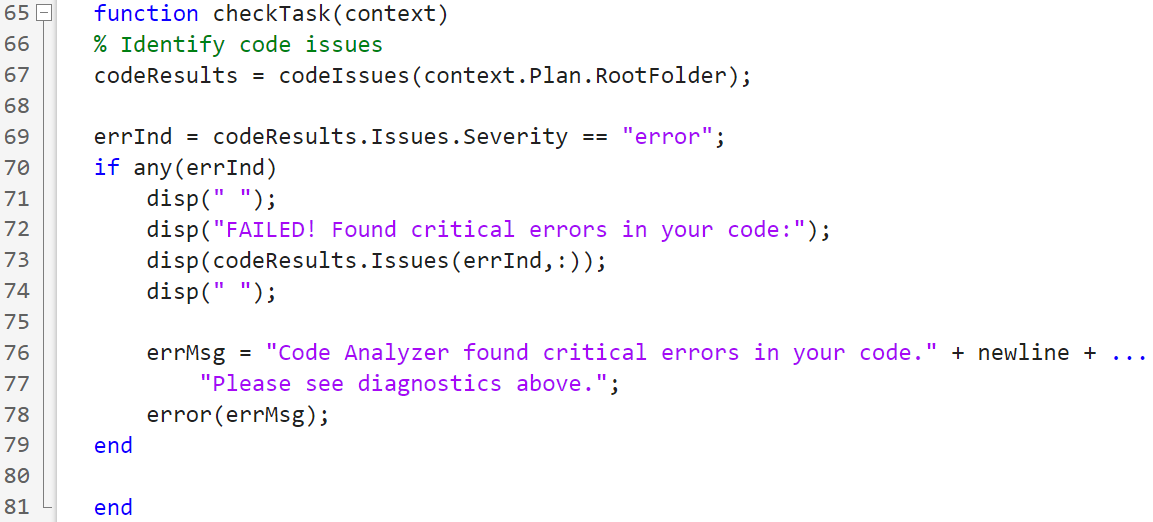

The `check` task will analyze all of the files in our project, and fail the build if it detects any code issues with a severity of "error."

Let's execute the `check` task using:

buildtool check

Oh no! We ran into our first build failure! 

It looks like `pokerHandStats.m` contains a coding practice that we wanted to disallow using our customized Code Analyzer configuration in **Step 6** of the workshop.

**8H)  Fixing our build failure**

Let's fix our `check` task failure by addressing the bad coding practice in [`pokerHandStats.m`](matlab:open('./Example_DependencyAnalyzer\pokerHandStats.m')).

This specific bad coding practice is because we are using "`ans`" as a variable. Since "`ans`" can be frequently overwritten by almost any MATLAB code during execution, it can lead to inconsistent and buggy behavior, and can be very hard to debug whenever something goes wrong.

We can easily navigate to this issue by running clicking on the [`pokerHandStats.m`](matlab:open('./Example_DependencyAnalyzer/pokerHandStats.m')) hyperlink in the previous step, or running the following command.

To resolve this issue, we can explicitly assign the output on line 24 to a variable, and use that variable on line 25 instead of "`ans`."

We have included a commented out code snippet (lines 32-33 in `pokerHandStats.m`) that you can use to easily resolve this issue.

              

Once we have updated the code, we can run the `check` task again to verify that our task completes successfully.

buildtool check

Congratulations! You just resolved your first build failure!

**8I)  Including the **`check`** task as a dependency in other tasks**

Making sure that no syntax errors or other error-level Code Analyzer issues make it into your code is critical for maintaining a high level of quality in your applications. To make sure that we always check for these kinds of issues, we can add the `check` task as a dependency of all of the other tasks.

To do this, let's open the [`buildfile.m`](matlab:open('./buildfile.m')) and:

- uncomment line 22

- uncomment line 27

***Note:***  Feel free to delete line 26, as it is superseded by line 27.

**8J)  Let's run our entire build in one command!**

Now let's clean out all of our results and try running our toolbox task again to see all of our tasks run together.

buildtool clean toolbox

Congratulations! You just automated your entire build process, and you are on your way to having a fully automated DevOps workflow!

## Workshop wrap-up and additional information

Congratulations for completing the "What's New for Managing, Testing, and Building your MATLAB Code" Workshop!

**During this workshop, you have successfully:**

- opened a GitHub repository in MATLAB Online with a single click

- explored the repository history using the Branch Manager

- identified and fixed a dependency issue using the Dependency Analyzer

- identified issues in the code using the `codeIssues` function

- configured the Code Analyzer to enable more strict code issue detection

- programmatically packaged a toolbox using the `ToolboxOptions` object

- automated the testing and packaging of a toolbox using the build tool

We hope these features help enable you to build more robust MATLAB applications!

**Check out these links for more information about the features we discussed:**

- "Open in MATLAB Online" badge creator:  [https://www.mathworks.com/products/matlab-online/git.html](https://www.mathworks.com/products/matlab-online/git.html)

- "Open in MATLAB Online" documentation:  [https://www.mathworks.com/help/matlab/matlab_env/open-github-repositories-in-matlab-online.html](https://www.mathworks.com/help/matlab/matlab_env/open-github-repositories-in-matlab-online.html)

- Dependency Analyzer overview:  [https://www.mathworks.com/help/matlab/matlab_prog/analyze-project-dependencies.html](https://www.mathworks.com/help/matlab/matlab_prog/analyze-project-dependencies.html)

- Code Analyzer app overview:  [https://www.mathworks.com/help/matlab/matlab_prog/matlab-code-analyzer-report.html](https://www.mathworks.com/help/matlab/matlab_prog/matlab-code-analyzer-report.html)

- `codeIssues` documentation: [https://www.mathworks.com/help/matlab/ref/codeissues.html](https://www.mathworks.com/help/matlab/ref/codeissues.html)

- Configure Code Analyzer overview:  [https://www.mathworks.com/help/matlab/matlab_env/configure-code-analyzer.html](https://www.mathworks.com/help/matlab/matlab_env/configure-code-analyzer.html)

- ToolboxOptions documentation:  [https://www.mathworks.com/help/matlab/ref/matlab.addons.toolbox.toolboxoptions.html](https://www.mathworks.com/help/matlab/ref/matlab.addons.toolbox.toolboxoptions.html)

- Build tool overview:  [https://www.mathworks.com/help/matlab/matlab_prog/overview-of-matlab-build-tool.html](https://www.mathworks.com/help/matlab/matlab_prog/overview-of-matlab-build-tool.html)

- Build tool blog post:  [https://blogs.mathworks.com/developer/2022/10/17/building-blocks-with-buildtool/](https://blogs.mathworks.com/developer/2022/10/17/building-blocks-with-buildtool/)

- Improve performance with incremental builds:  [https://www.mathworks.com/help/matlab/matlab_prog/improve-performance-with-incremental-builds.html](https://www.mathworks.com/help/matlab/matlab_prog/improve-performance-with-incremental-builds.html)

- CI Configuration Examples repository:  [https://github.com/mathworks/ci-configuration-examples](https://github.com/mathworks/ci-configuration-examples)

- CI with MATLAB and GitHub Actions Workshop:  [https://github.com/mathworks/ci-with-matlab-and-github-actions-workshop](https://github.com/mathworks/ci-with-matlab-and-github-actions-workshop)

Copyright 2023 The MathWorks, Inc.